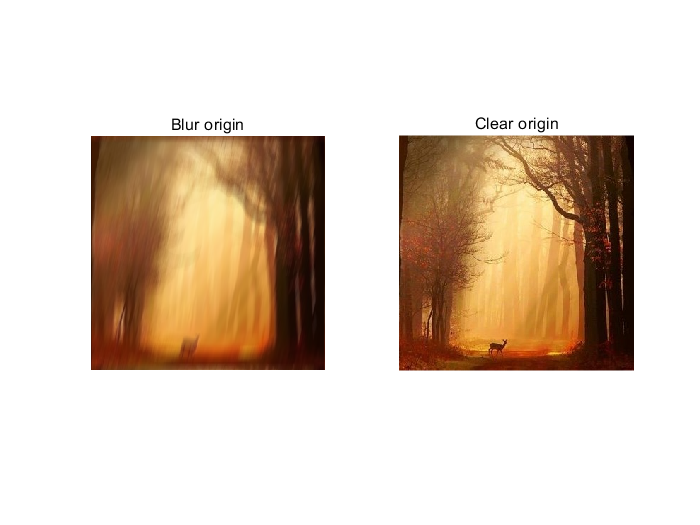

input = imread('hw2_files/Q3/1/1.png');
compared = imread('hw2_files/Q3/1/original1.jpg');
figure("Name","Blurred-Clear")
subplot(1,2,1),imshow(input),title("Blur origin");hold on
subplot(1,2,2),imshow(compared),title("Clear origin");hold off

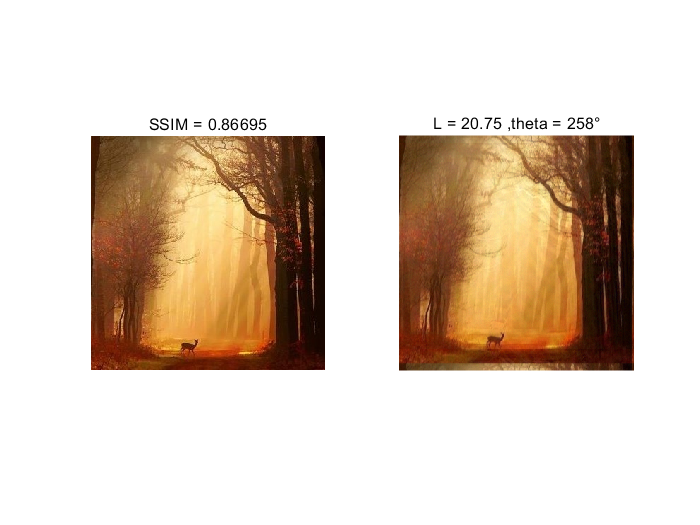

clf;
[row,col,~] = size(input);
if row ~= col
   input = ResizeSquare(input); 
end

weiner_recovered = zeros(size(input));
for i = 1:3
    [theta,L] = DetectMotionParameters(input(:,:,i));
    h = fspecial('motion',L,theta);
    pic = WeinerFilter(input(:,:,i),h,10);
    weiner_recovered(:,:,i) = pic;
end
weiner_recovered = uint8(imresize(weiner_recovered,[row,col]));
% rmse = RMSE(input,compared)
ssimval = ssim(compared,weiner_recovered);

figure("Name","Recovered-Clear"),
subplot(1,2,2),imshow(weiner_recovered),title("L = "+ L + " ,theta = "+ theta + "°");hold on
subplot(1,2,1),imshow(compared),title("SSIM = " + ssimval);hold off

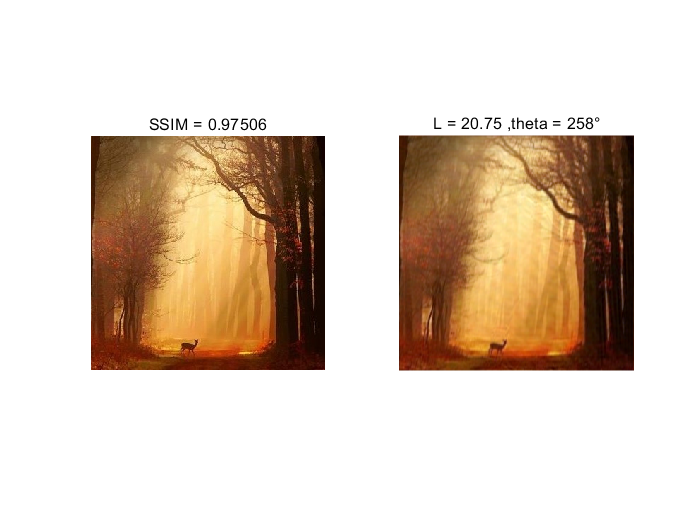

clf;
cls_recovered = zeros(size(input));
for i = 1:3
    [theta,L] = DetectMotionParameters(input(:,:,i));
    h = fspecial('motion',L,theta);
    testLayer = double(input(:,:,i));
    variant = var(testLayer(:))/1000000;
    
    pic = ConstraintLeastSquareFilter(input(:,:,i),h,variant);
    
    cls_recovered(:,:,i) = pic;
end
cls_recovered = uint8(imresize(cls_recovered,[row,col]));
% rmse = RMSE(input,compared)
ssimval = ssim(compared,cls_recovered);

figure("Name","Recovered-Clear");
subplot(1,2,2),imshow(cls_recovered),title("L = "+ L + " ,theta = "+ theta + "°");hold on
subplot(1,2,1),imshow(compared),title("SSIM = " + ssimval);hold off

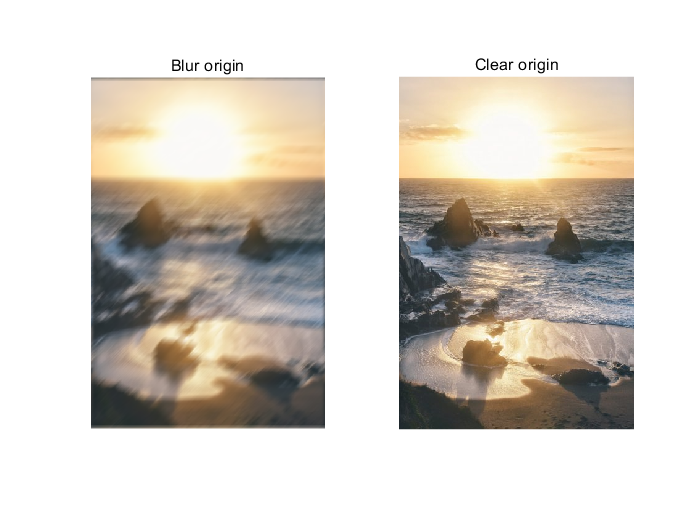

input = imread('hw2_files/Q3/2/2.png');
compared = imread('hw2_files/Q3/2/original2.jpg');
figure("Name","Blurred-Clear")
subplot(1,2,1),imshow(input),title("Blur origin");hold on
subplot(1,2,2),imshow(compared),title("Clear origin");hold off

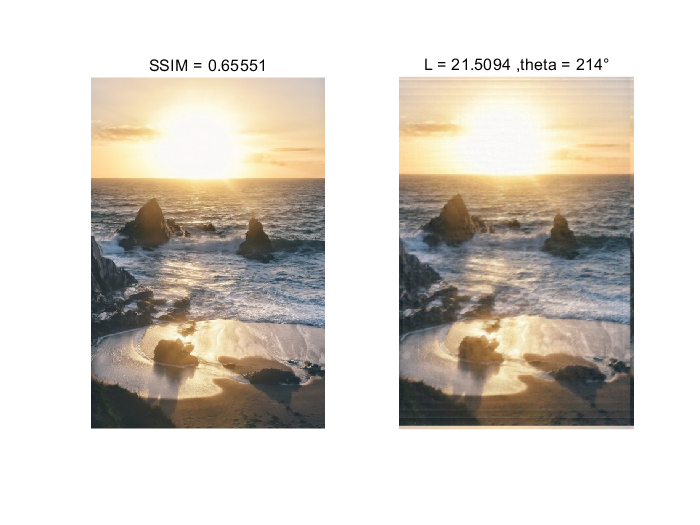

clf;
[row,col,~] = size(input);
if row ~= col
   input = ResizeSquare(input); 
end

weiner_recovered = zeros(size(input));
for i = 1:3
    [theta,L] = DetectMotionParameters(input(:,:,i));
    h = fspecial('motion',L,theta);
    pic = WeinerFilter(input(:,:,i),h,10);
    weiner_recovered(:,:,i) = pic;
end
weiner_recovered = uint8(imresize(weiner_recovered,[row,col]));
% rmse = RMSE(input,compared)
ssimval = ssim(compared,weiner_recovered);

figure("Name","Recovered-Clear"),
subplot(1,2,2),imshow(weiner_recovered),title("L = "+ L + " ,theta = "+ theta + "°");hold on
subplot(1,2,1),imshow(compared),title("SSIM = " + ssimval);hold off

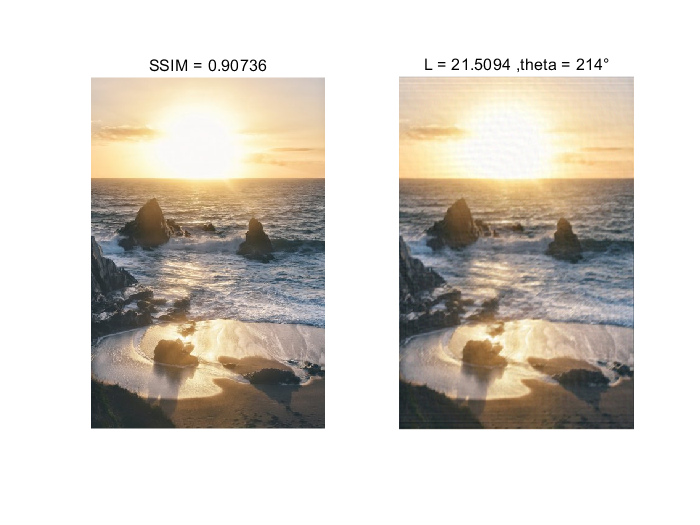

clf;
cls_recovered = zeros(size(input));
for i = 1:3
    [theta,L] = DetectMotionParameters(input(:,:,i));
    h = fspecial('motion',L,theta);
    testLayer = double(input(:,:,i));
    variant = var(testLayer(:))/1000000;
    
    pic = ConstraintLeastSquareFilter(input(:,:,i),h,variant);
    
    cls_recovered(:,:,i) = pic;
end
cls_recovered = uint8(imresize(cls_recovered,[row,col]));
% rmse = RMSE(input,compared)
ssimval = ssim(compared,cls_recovered);

figure("Name","Recovered-Clear");
subplot(1,2,2),imshow(cls_recovered),title("L = "+ L + " ,theta = "+ theta + "°");hold on
subplot(1,2,1),imshow(compared),title("SSIM = " + ssimval);hold off

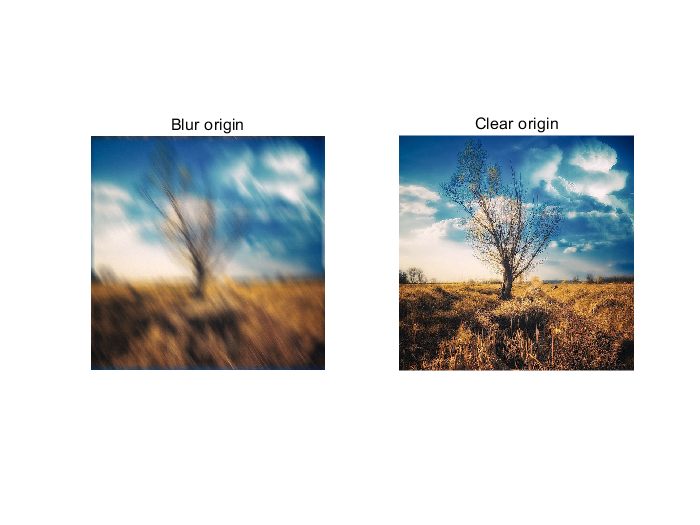

input = imread('hw2_files/Q3/3/3.png');
compared = imread('hw2_files/Q3/3/original3.jpg');
figure("Name","Blurred-Clear")
subplot(1,2,1),imshow(input),title("Blur origin");hold on
subplot(1,2,2),imshow(compared),title("Clear origin");hold off

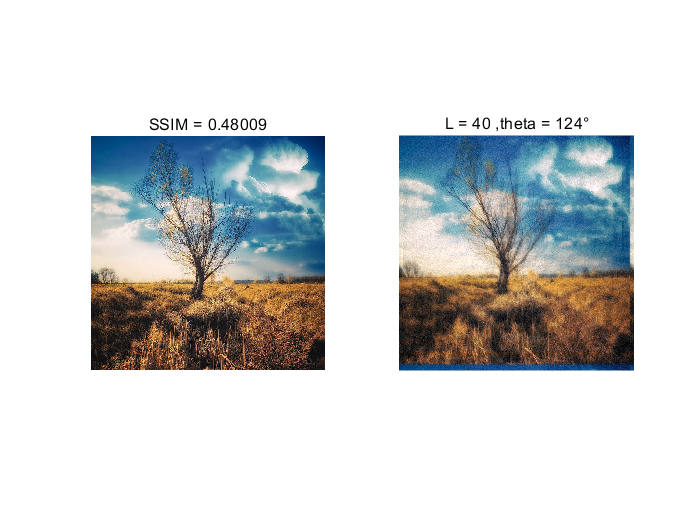

clf;
[row,col,~] = size(input);
if row ~= col
   input = ResizeSquare(input); 
end

weiner_recovered = zeros(size(input));
for i = 1:3
    [theta,L] = DetectMotionParameters(input(:,:,i));
    h = fspecial('motion',L,theta);
    pic = WeinerFilter(input(:,:,i),h,10);
    weiner_recovered(:,:,i) = pic;
end
weiner_recovered = uint8(imresize(weiner_recovered,[row,col]));
% rmse = RMSE(input,compared)
ssimval = ssim(compared,weiner_recovered);

figure("Name","Recovered-Clear"),
subplot(1,2,2),imshow(weiner_recovered),title("L = "+ L + " ,theta = "+ theta + "°");hold on
subplot(1,2,1),imshow(compared),title("SSIM = " + ssimval);hold off

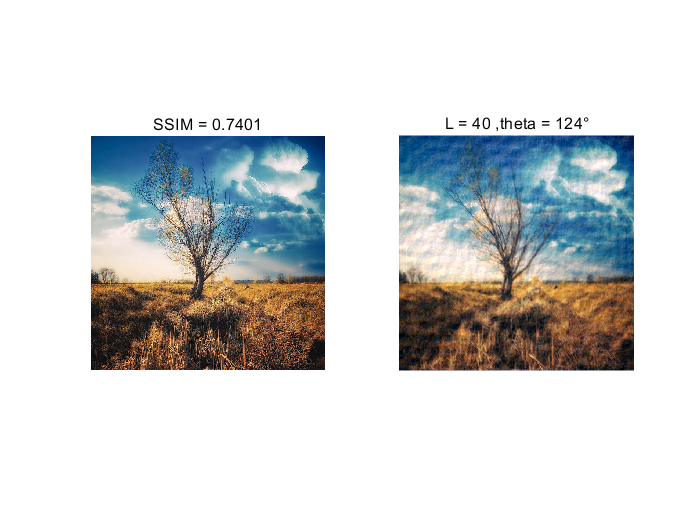

clf;
cls_recovered = zeros(size(input));
for i = 1:3
    [theta,L] = DetectMotionParameters(input(:,:,i));
    h = fspecial('motion',L,theta);
    testLayer = double(input(:,:,i));
    variant = var(testLayer(:))/1000000;
    
    pic = ConstraintLeastSquareFilter(input(:,:,i),h,variant);
    
    cls_recovered(:,:,i) = pic;
end
cls_recovered = uint8(imresize(cls_recovered,[row,col]));
% rmse = RMSE(input,compared)
ssimval = ssim(compared,cls_recovered);

figure("Name","Recovered-Clear");
subplot(1,2,2),imshow(cls_recovered),title("L = "+ L + " ,theta = "+ theta + "°");hold on
subplot(1,2,1),imshow(compared),title("SSIM = " + ssimval);hold off

function ret = WeinerFilter(layer, psf, K)
    [psf_row, psf_col] = size(psf);
    [row,col] = size(layer);
    psf_padded = zeros([row,col]);
    psf_padded(1:psf_row, 1:psf_col) = psf;
    psf_padded = psf_padded / sum(psf_padded,"all");
    psf_dft = fft2(psf_padded);
    
    testLayer = double(layer);
    estimated_nsr = K / var(testLayer(:));
    
    img_dft = fft2(layer);
    psf_dft_abs = abs(psf_dft).^2;
    dmp_factor = psf_dft_abs./(psf_dft_abs+estimated_nsr*ones([row,col]));
    layer_psf_fft_ratio = img_dft./psf_dft;
    result = abs(ifft2(dmp_factor.*layer_psf_fft_ratio));
    ret = uint8(result);
end

function ret = ConstraintLeastSquareFilter(layer,psf,gamma)
    layer = double(layer);
    [row,col] = size(layer);
    
    img_dft = fft2(layer);
    
    psf_padded = psf2otf(psf, [row,col]);
    
    laplacian = [0,-1,0;-1,4,-1;0,-1,0];
    laplacian_padded = psf2otf(laplacian,[row,col]);
    
    numerator = conj(psf_padded);
    denominator = psf_padded.^2+gamma*(laplacian_padded.^2);
    
    result = ifft2(numerator.*img_dft./denominator);
    ret = uint8(result);
end

function [theta,L] = DetectMotionParameters(layer)
    [row,col] = size(layer);
    fshift = fftshift(fft2(layer));
    magintude = 15*log(abs(fshift));
    
    T = 1-imbinarize(uint8(magintude),"adaptive","Sensitivity",0.65);
    kernel = ones([3,3],"uint8");
    morph = imopen(T,kernel);
    kernel = ones([1,9],"uint8");
    morph = imclose(morph,kernel);
    BW1 = edge(morph,'Canny');
    
    [H,T,R] = hough(BW1);
    P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
    lines = houghlines(BW1,T,R,P,'FillGap',5,'MinLength',7);
    theta_rotate = lines(1).theta;
    theta = 180-theta_rotate;
    
    rotated = imrotate(uint8(magintude),theta_rotate);
%     imshow(rotated)
    
    proj = sum(rotated,1);
    xaxis = 1: length(proj);
%     figure;
%     plot(xaxis,proj);
    
    [~,maxIndex] = max(proj);
    for i = 1:100
        if proj(maxIndex-i) - proj(maxIndex-i-1) < -1000
            index_1 = i;
            break
        end
    end
    for i = 1:100
        if proj(maxIndex+i) - proj(maxIndex+i+1) < -1000
            index_2 = i;
            break
        end
    end
    
    if abs(index_1 - index_2) >= 5
        index_1 = max([index_1, index_2]);
        index_2 = max([index_1, index_2]);
    end
    
    L = 2 * col / (index_1 + index_2);
end

function ret = ResizeSquare(img)
    [row,col,~] = size(img);
    if row > col
        n = row;
    else
        n = col;
    end
    ret = imresize(img,[n,n]);
end

function ret = RMSE(img,compared)
    [row,col] = size(compared);
    squares = (img-compared).^2;
    sum_squares = sum(squares,"all");
    ret = sqrt(sum_squares/(3*row*col));
end